# MATLAB을 활용한 AI 프로그래밍 - 충남대학교 김병관

- 한국전자파학회 2023 하계 전파교육 단기강좌 (8월 4일, 11일) 

- 문의사항: byungkwan.kim@cnu.ac.kr 

# 2. Introduction to CNN

## [ Activity 1 ] 정규화 (Dropout Layer)의 유무

- 코드 그대로 학습을 진행 해 보세요.

- Dropout Layer 를 주석 해제 하고 학습을 진행 해 보세요.  [ line 14 ]

- Dropout Layer 의 비율을 0.1, 0.5, 0.9 로 진행 해 보세요.

- 훈련 및 검증 정확도에 어떠한 차이가 있는지 확인 해 보세요

## [ Activity 2 ] 필터 개수의 영향 및 학습 회수

- Dropout Layer 를 0.5로 설정 한 상태에서, [ line 14 ]

- convolution2dLayer의 필터 수를 32/64에서 16/32로 변경해서 진행 해 보세요. [ line 10, 16 ] 

- convolution2dLayer의 필터 수를 32/64에서 64/128로 변경해서 진행 해 보세요.

- 충분하게 수렴 되지 않는 경우, 아래 옵션에서 MaxEpoch 를 늘려서 진행 해 보세요.

### 1) Import image data into MATLAB workspace

- 학습에 사용될 Image는 각각 폴더 내에 존재함. **(MATLAB 현재 폴더 확인)**

- 폴더 명을 Label 로 인식하는 Option 추가 ('LabelSource','foldernames')

- Image size는 픽셀 가로/세로 크기, RGB이므로 [72 72 3] 의 행렬 형태로 표현

- 신호 종류는 총 10가지 (numClasses)

inputSize = [72 72 3];
numClasses = 9;
hf_radio = imageDatastore("./", "IncludeSubfolders",true,"FileExtensions",'.png','LabelSource','foldernames');

- **빠른 학습을 위해, 전체 1000개 중 250개만 가지고 수행**

- 1000개를 읽어온 뒤, 무작위로 순서를 섞고, 250개를 추출 해 냄

- 추출된 250개의 Dataset을 Train 및 Validation 으로 7:3 비율로 무작위로 분리

hf_radio_shuffle = shuffle(hf_radio);
hf_radio_split = partition(hf_radio_shuffle, 4, 1);
[hf_radio_train, hf_radio_val] = splitEachLabel(hf_radio_split,0.7,'randomized');

### 2) Configure Neural Network using MATLAB Machine Learning Toolbox

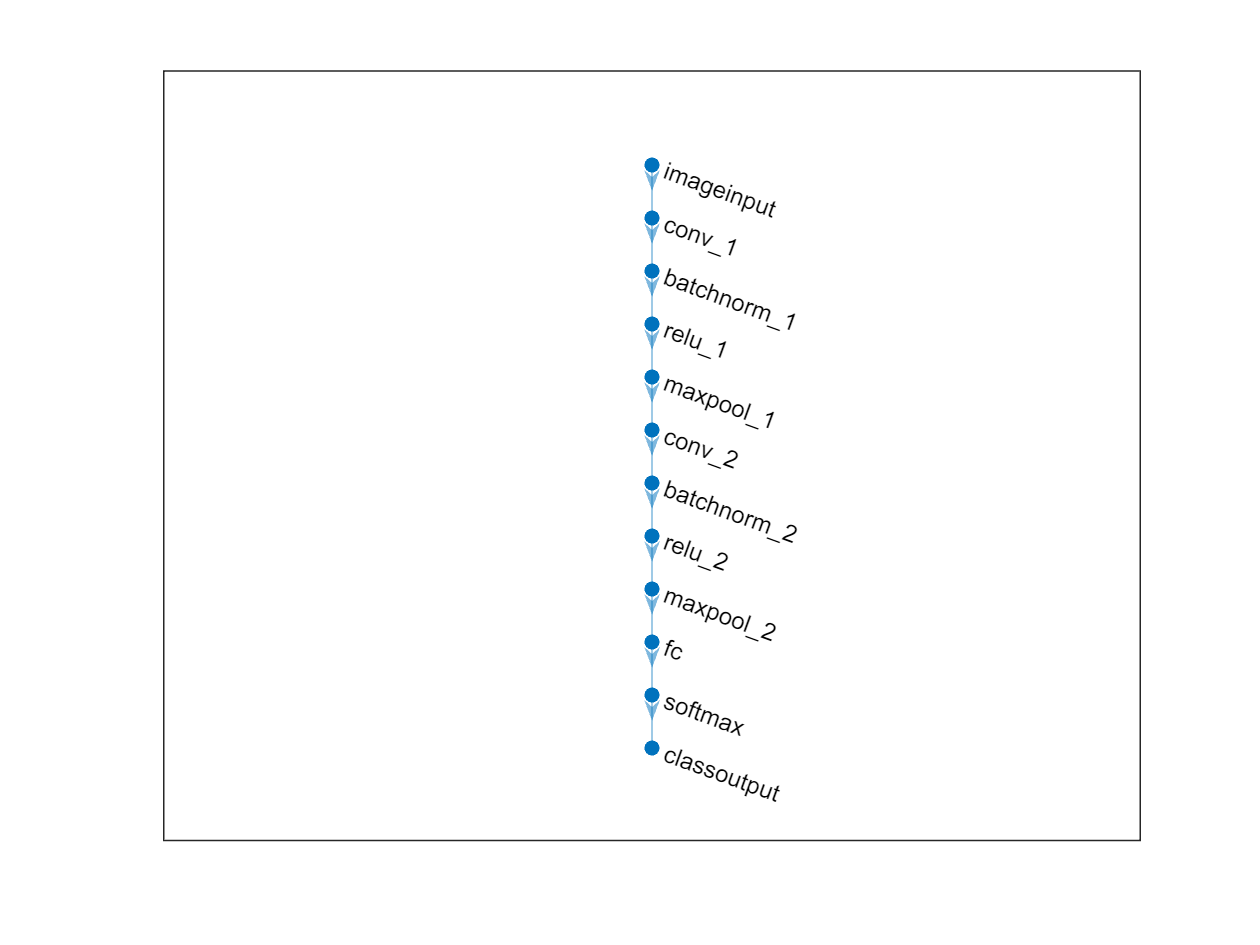

layers = [
    imageInputLayer(inputSize)

    convolution2dLayer(3,64,'Padding','same')   
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2)
    % dropoutLayer(0.5)                 

    convolution2dLayer(3,128,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2)

    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

lgraph = layerGraph(layers);
plot(lgraph)

analyzeNetwork(lgraph)

### 3) Convolutional Neural Network 학습을 위한 변수 설정 

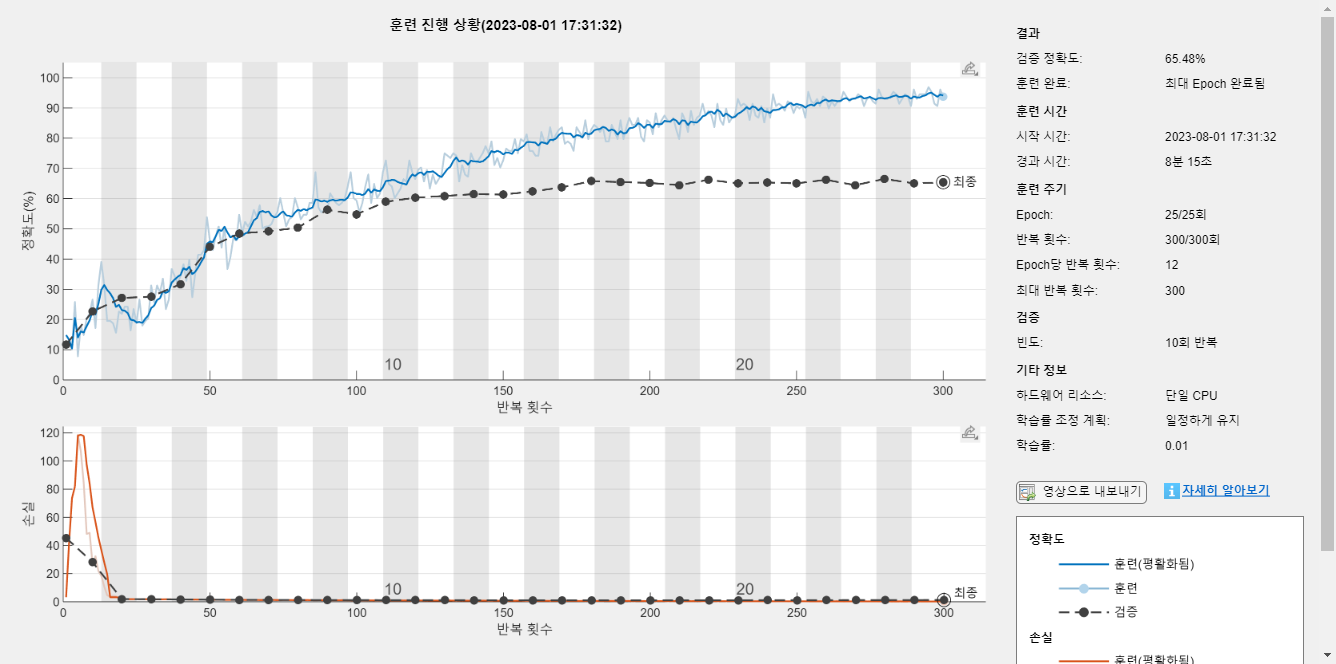

options = trainingOptions('sgdm', ...
    'MaxEpochs',25, ...
    'ValidationData',hf_radio_val, ...
    'ValidationFrequency',10, ...
    'Verbose',false, ...
    'Plots','training-progress', ...
    ExecutionEnvironment='cpu');

net = trainNetwork(hf_radio_train,layers,options);

### 4) 정확도 분석을 위한 Inference (추론) 수행 

- YPred 라는 변수에 Network 가 추론한 결과값이 저장되며,

- YValidation 및 YTrain은 학습을 위해 제공한 정답 Label이 들어 있음.

YPred = classify(net,hf_radio_val);
YValidation = hf_radio_val.Labels;
YTrain = hf_radio_train.Labels;
accuracy = mean(YPred == YValidation);
YTrainPred = classify(net,hf_radio_train);
validationError = mean(YPred ~= YValidation);
trainError = mean(YTrainPred ~= YTrain);
disp("Accuracy: " + accuracy*100 + "%");

Accuracy: 65.4815%


disp("Training error: " + trainError*100 + "%");

Training error: 7.6825%


disp("Validation error: " + validationError*100 + "%");

Validation error: 34.5185%


### 5) Class 별 정확도 분석을 위한 Confusion Matrix 결과 확인 방법 

- confusionchart 명령어를 통한 분석 툴 제공

- Normalize 등의 옵션 설정 가능 

- [https://kr.mathworks.com/help/stats/confusionchart.html](https://kr.mathworks.com/help/stats/confusionchart.html)

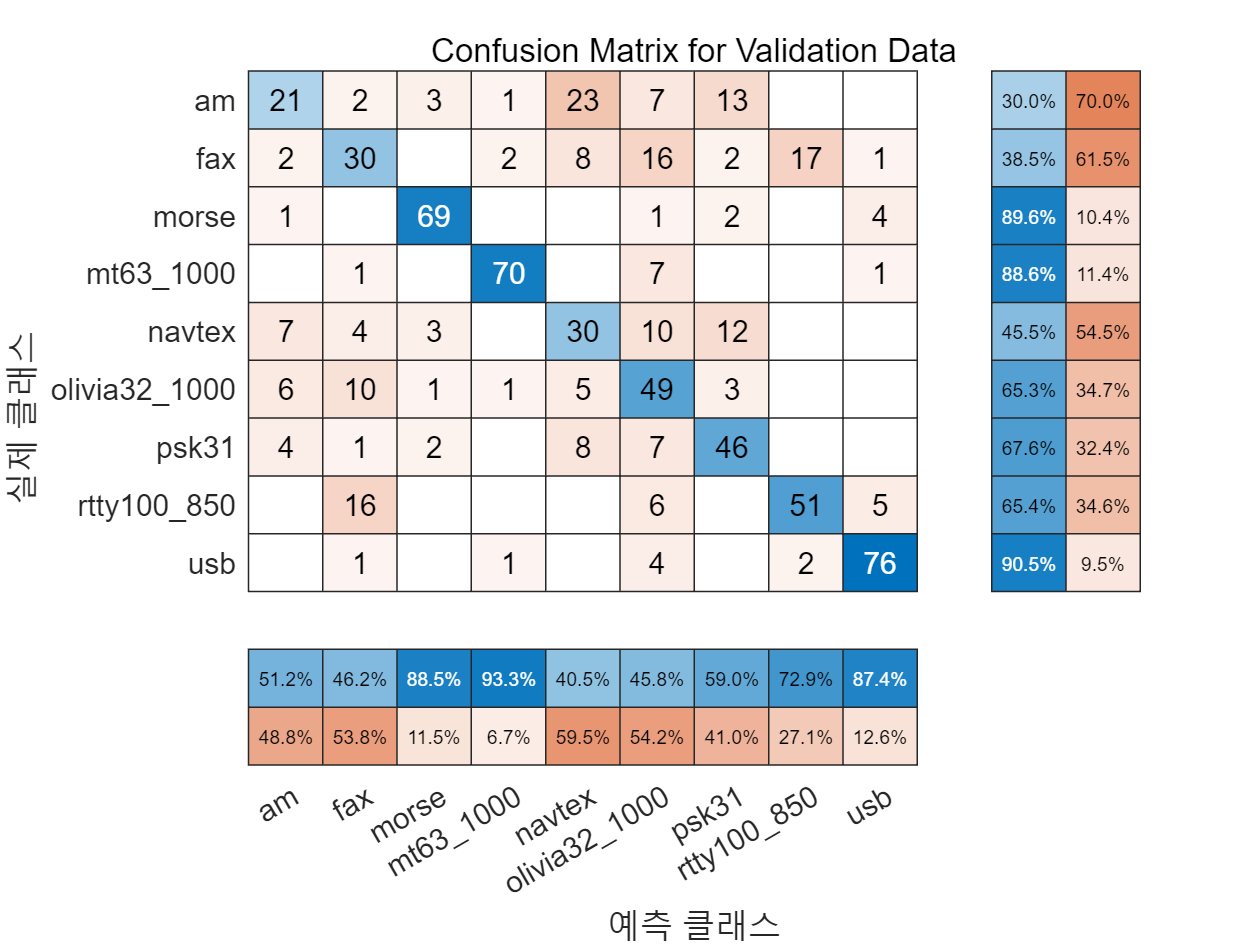

cm = confusionchart(YValidation,YPred);
cm.Title = 'Confusion Matrix for Validation Data';
cm.ColumnSummary = 'column-normalized';
cm.RowSummary = 'row-normalized';